#### **Changing the shades of image**

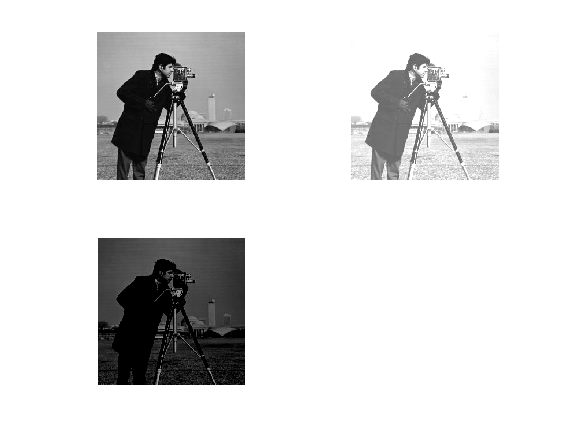

i=imread('cameraman.tif');
i1 =  i+100; %increase brightness
i2 = i-100; %dark image
i3 = i+50;
clf;
subplot(2,2,1);imshow(i);
subplot(2,2,2);imshow(i1);
subplot(2,2,3);imshow(i2);

#### SUBPLOTS

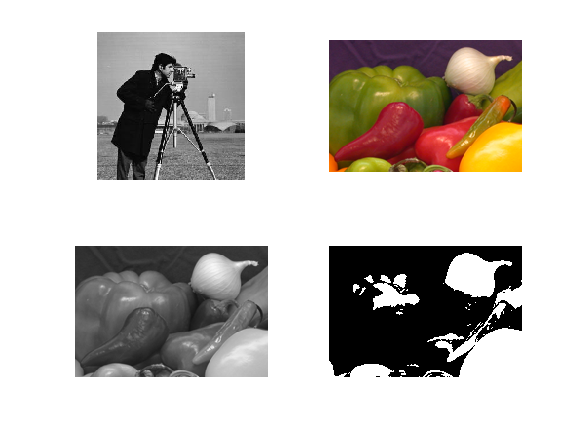

veg1=imread('onion.png');
veg2=rgb2gray(veg1); %converting color to grey
veg3=imbinarize(veg2); %converting image to binary
subplot(2,2,1);imshow(i);
subplot(2,2,2);imshow(veg1);
subplot(2,2,3);imshow(veg2);
subplot(2,2,4);imshow(veg3);

#### To load image

imread('cameraman.tif');

#### To display image

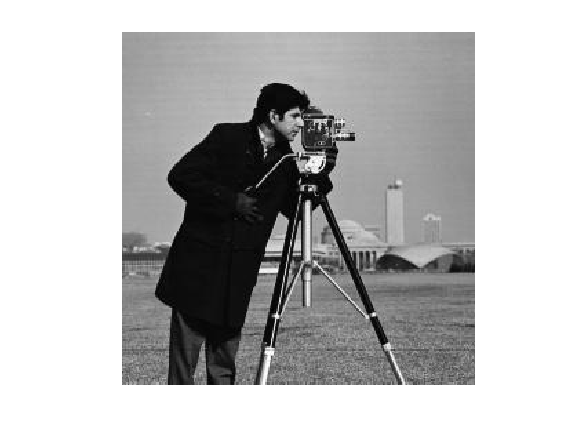

clf;
imshow('cameraman.tif');

#### Assigning to a variable

clf;
ii=imread('cameraman.tif');
imshow(ii);

#### Increasing the brightness of image

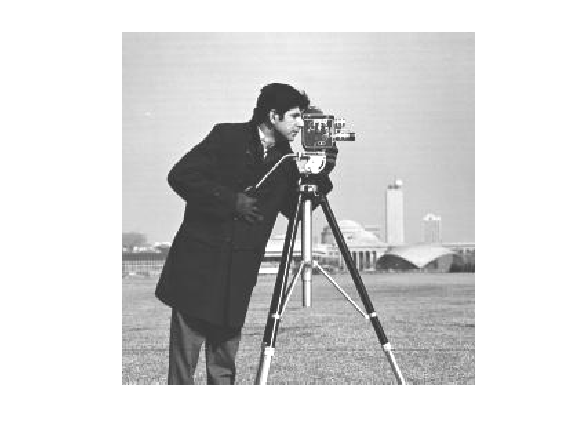

clf;
ii1=ii+50;
imshow(ii1);

#### Decreasing the brightness of image

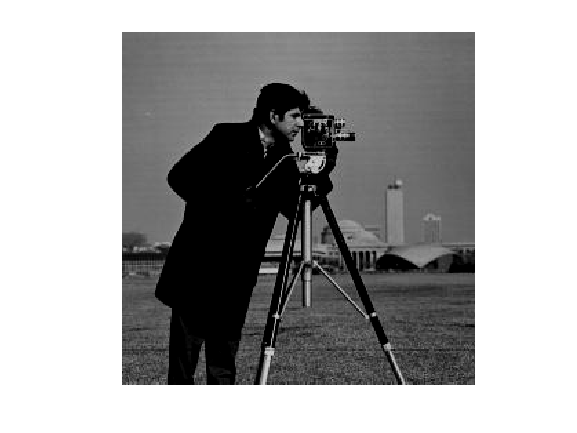

ii2=ii-50;
imshow(ii2);

#### Divsion operator on the image

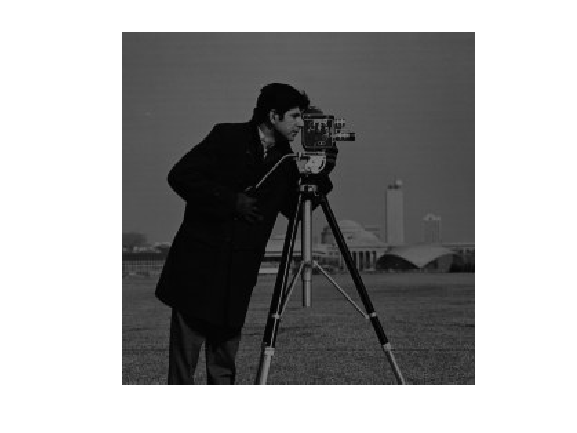

ii3=ii/2;
imshow(ii3);

#### To see the information of the image

imfinfo('cameraman.tif')

ans = struct with fields:
           Filename: '/MATLAB Drive/cameraman.tif'
        FileModDate: '24-Jan-2021 07:33:20'
           FileSize: 10717
             Format: 'jpg'
      FormatVersion: ''
              Width: 256
             Height: 256
           BitDepth: 8
          ColorType: 'grayscale'
    FormatSignature: ''
    NumberOfSamples: 1
       CodingMethod: 'Huffman'
      CodingProcess: 'Sequential'
            Comment: {}


#### To convert on image format

imwrite(ii,'cameraman.tif',"jpg");
disp(imfinfo('cameraman.jpg'));

           Filename: '/MATLAB Drive/cameraman.jpg'
        FileModDate: '20-Jan-2021 08:12:36'
           FileSize: 10717
             Format: 'jpg'
      FormatVersion: ''
              Width: 256
             Height: 256
           BitDepth: 8
          ColorType: 'grayscale'
    FormatSignature: ''
    NumberOfSamples: 1
       CodingMethod: 'Huffman'
      CodingProcess: 'Sequential'
            Comment: {}



#### Displaying Pout Image

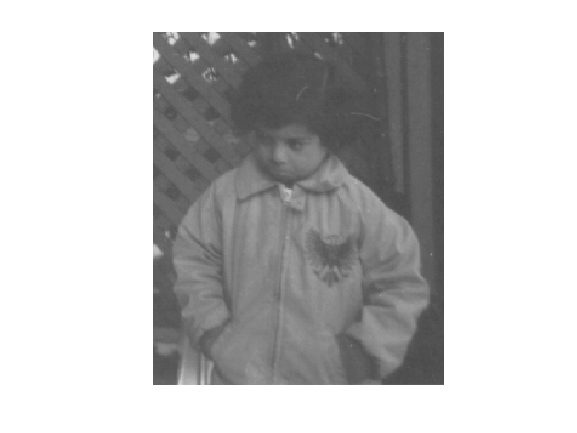

imshow('pout.tif')

#### Display Cell Image

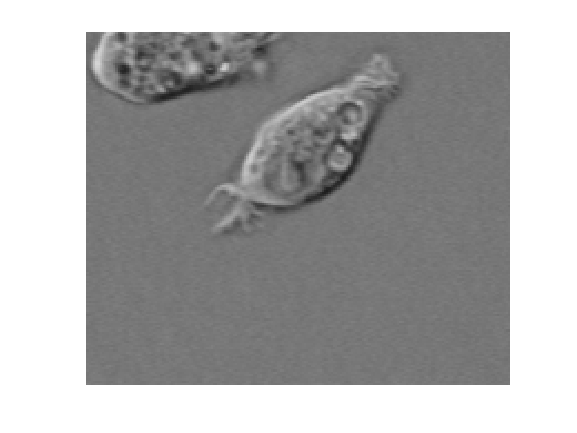

imshow('cell.tif')

#### Display Onion Image

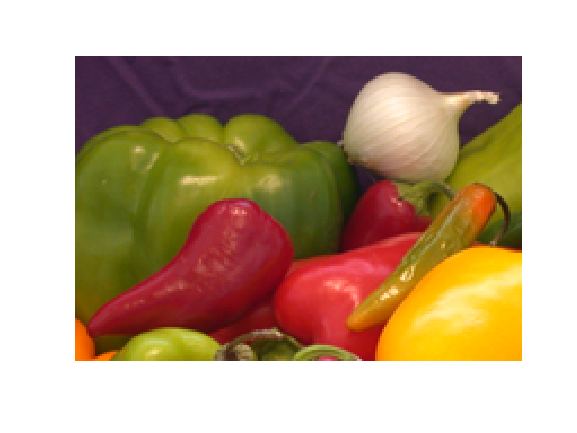

imshow('onion.png');

#### Summation

disp(sum(ii));

  Columns 1 through 14

   36393          36784          36886          37028          36982          37199          37282          37185          37546          37764          37759          37310          37561          37569       

  Columns 15 through 28

   37782          37875          37958          37891          37732          38262          38371          38611          38304          38617          37810          37559          37084          36603       

  Columns 29 through 42

   36045          35642          35515          35332          35121          33144          29853          27482          25679          25278          24518          23754          23192          22788       

  Columns 43 through 56

   22189          21825          21366          20318          19213          18795          18725          18768          18512          18225          18632          18809          18968          19171       

  Columns 57 through 70

   19658          19851     

disp(sum(sum(ii)));

 7780286       



#### KNOWING ABOUT THE USAGE OF THE CMDS

lookfor imread

readDatastoreImage             - Read file formats supported by IMREAD.
waitsimready                   - (donefile, wait_time)
imread                         - Read image from graphics file.
cachedFormat                   - access and modify image format cached by last imread call


help imshow

 imshow Display image in Handle Graphics figure.  
    imshow(I) displays the grayscale image I.
 
    imshow(I,[LOW HIGH]) displays the grayscale image I, specifying the display
    range for I in [LOW HIGH]. The value LOW (and any value less than LOW)
    displays as black, the value HIGH (and any value greater than HIGH) displays
    as white. Values in between are displayed as intermediate shades of gray,
    using the default number of gray levels. 
 
    imshow(I,[]) displays the grayscale image I scaling the display based
    on the range of pixel values in I. imshow uses [min(I(:)) max(I(:))] as
    the display range, that is, the minimum value in I is displayed as
    black, and the maximum value is displayed as white.
 
    imshow(RGB) displays the truecolor image RGB.
 
    imshow(BW) displays the binary image BW. imshow displays pixels with

# ACH2

#### FORMATING COMMANDS

format long;
x = 7 + 10/3 + 5 ^ 1.2;
x

x =   17.231981640639408


format short;
x = 7 + 10/3 + 5 ^ 1.2;
x

x = 17.2320

format short e;
disp(4.678*4.9);

   2.2922e+01



format long e;
x=pi;
x

x =      3.141592653589793e+00


format rat;
disp(4.678*4.9);

    2063/90    



### if... end Statement

a = 10;
% check the condition using if statement
if a < 20
    % if condition is true then print the following
    fprintf('a is less than 20\n');
end

a is less than 20


fprintf('value of a is : %d\n',a);

value of a is : 10


### if...else...end Statement

a = 100;
% check the boolean condition
    if a < 20
        % if condition is true then print the following
        fprintf('a is less than 20\n');
    else
        % if condition is false then print the following
        fprintf('a is not less than 20\n');
    end

a is not less than 20


fprintf('value of a is : %d\n',a);

value of a is : 100


### if...elseif...elseif...else...end Statements

a = 100;
%check the boolean condition
    if a == 10
        % if condition is true then print the following
        fprintf('Value of a is 10\n');
    elseif( a == 20 )
        % if else if condition is true
        fprintf('Value of a is 20\n');
    elseif a == 30
        % if else if condition is true
        fprintf('Value of a is 30\n');
    else
        % if none of the conditions is true '
        fprintf('None of the values are matching\n');
    end

None of the values are matching


fprintf('Exact value of a is: %d\n',a);

Exact value of a is: 100


### The Nested if Statements

a = 100;
b = 200;
% check the boolean condition
    if( a == 100 )
        % if condition is true then check the following
        if( b == 200 )
            % if condition is true then print the following
            fprintf('Value of a is 100 and b is 200\n');
        end
    end

Value of a is 100 and b is 200


fprintf('Exact value of a is : %d\n',a);

Exact value of a is : 100


fprintf('Exact value of b is : %d\n',b);

Exact value of b is : 200


### The Switch Statement

grade = 'B';
    switch(grade)
    case 'A'
        fprintf('Excellent!\n');
    case 'B'
        fprintf('Well done\n');
    case 'C'
        fprintf('Well done\n');
    case 'D'
        fprintf('You passed\n');
    case 'F'
        fprintf('Better try again\n');
    otherwise
        fprintf('Invalid grade\n');
    end

Well done


### The Nested switch Statements

ch1='A';
ch2='B';
    switch(ch1)
        case 'A'
            fprintf('This A is part of outer switch');
            switch(ch2)
                case 'A'
                    fprintf('This A is part of inner switch');
                case 'B'
                    fprintf('This B is part of inner switch');
            end
        case 'B'
            fprintf('This B is part of outer switch');
    end

This A is part of outer switch

This B is part of inner switch

a = 100;
b = 200;
    switch(a)
        case 100
            fprintf('This is part of outer switch %d\n',a);
            switch(b)
                case 200
                    fprintf('This is part of inner switch %d\n',a);
            end
    end

This is part of outer switch 100


This is part of inner switch 100


fprintf('Exact value of a is : %d\n',a);

Exact value of a is : 100


fprintf('Exact value of b is : %d\n',b);

Exact value of b is : 200


### WHILE LOOP

a = 1;
% while loop execution 
    while( a < 5 )
        fprintf('value of a: %d\n', a);
        a = a + 1;
    end

value of a: 1
value of a: 2
value of a: 3
value of a: 4


### FOR LOOP

for a = 1.0: -0.1: 0.0
   disp(a)
end

       1       

       9/10    

       4/5     

       7/10    

       3/5     

       1/2     

       2/5     

       3/10    

       1/5     

       1/10    

       0       



### NESTED LOOP

for i = 2:50
   for j = 2:50
      if(~mod(i,j)) 
         break; % if factor found, not prime
      end 
   end
   if(j > (i/j))
      fprintf('%d is prime\n', i);
   end
end

2 is prime
3 is prime
5 is prime
7 is prime
11 is prime
13 is prime
17 is prime
19 is prime
23 is prime
29 is prime
31 is prime
37 is prime
41 is prime
43 is prime
47 is prime


# ACH3

### DATA TYPES

str = 'Hello World!';
str

str = 'Hello World!'

n = 2345;
n

n =     2345       


d = double(n);
d

d =     2345       


un = uint32(789.50);
un

un = uint32
   790


rn = 5678.92347;
rn

rn =    73826/13    


c = int32(rn);
c

c = int32
   5679


NAME='R.SAILAJA';
NAME

NAME = 'R.SAILAJA'

n=str2double(NAME);
n

n =        0/0     


# ACH5

### FUNCTIONS

a=10;
b=sq(a);
disp(b);

     100       



disp(sq(a)); % All display 1000

     100       



disp(sq(10));

     100       



function y=sq(x)
% Sq(x) returns the squareof x
y = x * x;
end